# Kmeans : ImageSegmentation

## **Image Segmentation 1 - kmeans function ver.**

**'kmeans' function**: general data clustering

clear; clc; close all;

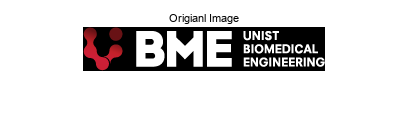

% Read an image
img = imread('Kmeans_BME.png');
figure(1),clf,imshow(img)
title('Origianl Image')

Make proper clusters from the image using K-means algortihms

K = 3;

X = double(reshape(img, [size(img,1)*size(img,2) 3]));  % Resize the matrix

[c_num c_mean] = kmeans(X,K);

c_num_mat = reshape(c_num, [size(img,1) size(img,2)]);  % Return to original matrix shape

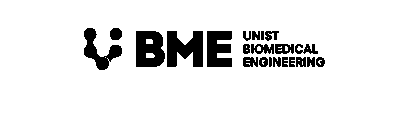

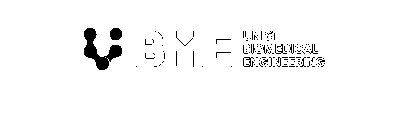

% Visualization of each cluster 
for c = 1:K
    [r c] = find(c_num_mat == c);   % find pixel assigned to c-th cluster
    
    for i = 1:length(r)
        segRGB(r(i),c(i),:) = [250 250 250];    % masking : white
    end
    
    figure; clf; imshow(segRGB)
    pause();
end

## **Image Segmentation 2 - imsegkmeans function ver.**

**'imsegkmeans' function**: specialized for image segmentation 

clear; clc; close all;

% Read an image
img = imread('Kmeans_BME.png');
figure(1),clf,imshow(img);
title('Origianl Image')

% Image segmentation with K-means
K = 3;
[L, Centers] = imsegkmeans(img,K);
clustered = labeloverlay(img,L);

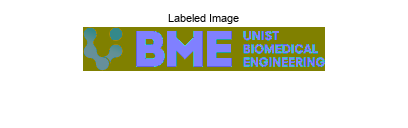

figure(2)
imshow(clustered)
title("Labeled Image")

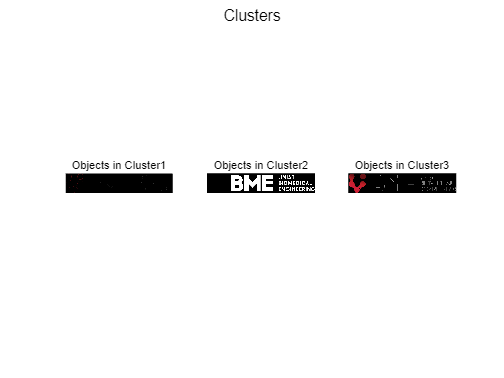

figure(3)
for i = 1:K
    subplot(1,3,i)
    mask = [L == i];
    cluster = img.*uint8(mask);
    imshow(cluster)
    title(['Objects in Cluster' num2str(i)])
end
sgtitle('Clusters')

## **Image Segmentation 3 - algorithm ver.**

clear; clc; close all;

**Read Image**

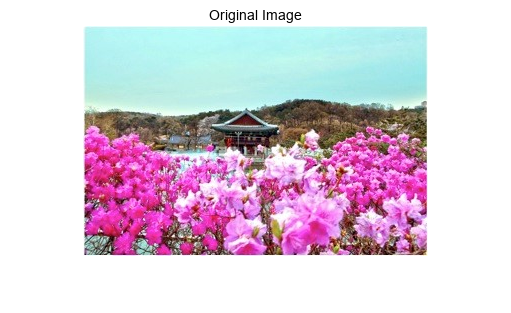

img = imread('Kmeans_nature.jpg');
figure(1),clf,imshow(img);
title('Original Image');

**Image Segmentation**

N1 = size(img,1);   % image length
N2 = size(img,2);   % image width
N = N1*N2;

% Initialize the cluster mean (Centroid)
K = 3;

for k = 1:K
    u(k,:) = 250*rand(1,3);    % Initialize cluster centers with random RGB values between 0 and 250
end

**K-means**

1
2
3
4
5
6
7
8
9
10


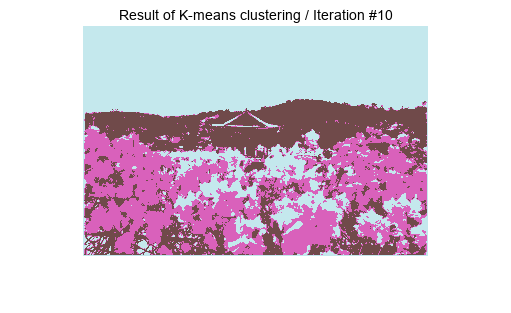

NumIter = 10;
for iter = 1:NumIter
    
    disp(num2str(iter));
    r = zeros(N1,N2);    % label
    total_d = 0;
    
    % E-step (Expectation-step)
    for n = 1:N1    
        for m = 1:N2    
            RGB = double(squeeze(img(n,m,:)));   % Extract RGB value of pixel (n,m)
            d = sum((repmat(RGB',K,1)-u).^2,2);  % Compute the Euclidean distance from each cluster center
            [min_d r(n,m)] = min(d);             % assign the pixel to the closest cluster
            total_d = total_d + min_d;           % Accumulate the minimun distance
        end
    end
    D = total_d/N;
    J(iter) = D;
    
    % M-step (Maximization-step)
    segRGB = img;
    for k = 1:K
        [ri ci] = find(r == k);                   % find the pixels assigned to cluster k
        L = length(ri);
        if L > 0
            % update the centroid
            S = zeros(1,3);                       % initialize sum for RGB values of cluster k
            for j = 1:L
                S = S+double(squeeze(img(ri(j),ci(j),:)))';     % sum all pixel RGB values
            end
            u(k,:) = S./L;                         % update centroid: mean RGB value of all pixels in cluster k
            % assign mean RGB colors to each pixel
            for j = 1:L
                segRGB(ri(j),ci(j),:) = u(k,:); 
            end
        end
    end

    % Show the results of clustering step-by-step
    figure(2),clf,imshow(segRGB)
    title(['Result of K-means clustering / Iteration #' num2str(iter)])
    pause(.1)

end

**Plot**

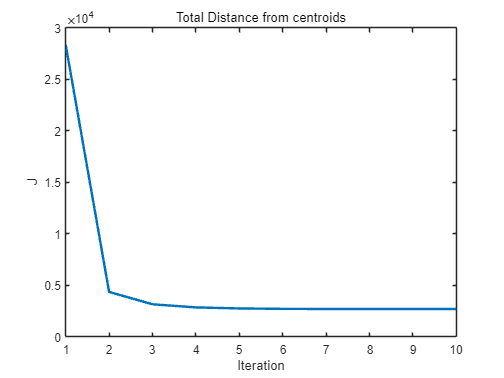

% Plot the total distance
figure(3),clf
plot(J, 'LineWidth',2)
xlabel('Iteration')
ylabel('J')
title('Total Distance from centroids')